clc;
clear all;
warning off;
%     A1     b1      A2      b2      A5      b5      Tp      Tf     Tvl
%     Tv0    yita    S1      S2      S3      S4      k0      k1     k2      k3
lb = [
      0       %A3
      0       %b3
      0       %A4
      0       %b4
      0       %A5
      0       %b5
      0       %k0
      0       %k1
      0       %k2
      0       %k3
      0       %XCP
     ]; 

ub = [
      0.5     %A3
      0.5     %b3
      0.5     %A4
      0.5     %b4
      0.5     %A5
      0.5     %b5
      0.5     %k0
      0.5     %k1
      0.5     %k2
      0.5     %k3
      0.5     %XCP
     ];    

Npara = length(lb); 

A3   = 0.2           ; b3   = 0.2           ;
A4   = 0.1           ; b4   = 0.1           ;
A5   = 0.1           ; b5   = 0.3           ;
k0   = 1             ; k1   = 1             ; 
k2   = 1             ; k3   = 1             ;
xcp = 0.2;

para_init = [A3,b4,A4,b4,...
            A5,b5,k0,k1,...
            k2,k3,xcp];

%% ==================== 1. 工况设置 ============================
meanangle    = 5;
averageangle = 10;
conditions   = input_condition(meanangle,averageangle);
airfoildata  = input_afdata;

错误使用 readmatrix (第 11 行)
找不到或无法打开 'FFA_W3_211.txt'。请检查路径和文件名或文件权限。

出错 input_afdata (第 2 行)
    data    = readmatrix('FFA_W3_211.txt');
    ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^


CFDdatapath = 'FFA_W3_211_rlt_5.txt';

%% ==================== 2. 整理变量 ============================
setcase.meanangle    = meanangle;
setcase.averageangle = averageangle;
setcase.conditions   = conditions;
setcase.airfoldata   = airfoildata;
setcase.CFDdatapath  = CFDdatapath;

para_local_GZ = run_optimal_GZ(para_init,Npara,lb,ub,setcase);

===== 动态失速BL模型参数优化开始【CFD拟合+面积相似度】 =====

单目标优化:
11 变量
1 非线性不等式约束

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1          12675      0.692379            0      0
    2          25094      0.692371            0      0
优化结束: 适应度值的平均变化小于 options.FunctionTolerance 且约束违反值小于 options.ConstraintTolerance。
===== 优化完成！最优适应度值 = 0.69237136 =====

==================== 原始参数 ↔ 优化后最优参数 对比表 ====================
原始适应度=4.971252 | 优化适应度=4.971252
   A3 : 原始值=0.200000 | 优化值=0.372647
   b3 : 原始值=0.100000 | 优化值=0.096746
   A4 : 原始值=0.100000 | 优化值=0.367155
   b4 : 原始值=0.100000 | 优化值=0.407479
   A5 : 原始值=0.100000 | 优化值=0.435544
   b5 : 原始值=0.300000 | 优化值=0.214427
   k0 : 原始值=1.000000 | 优化值=0.160204
   k1 : 原始值=1.000000 | 优化值=0.012212
   k2 : 原始值=1.000000 | 优化值=0.20993

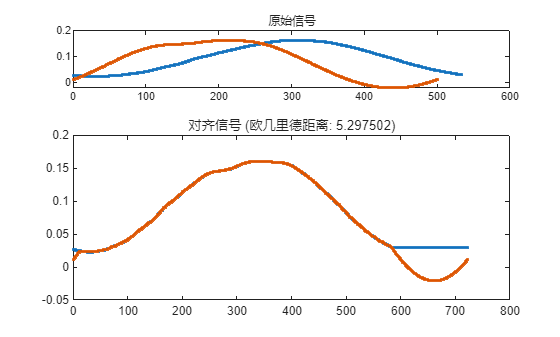

ans = 5.2975

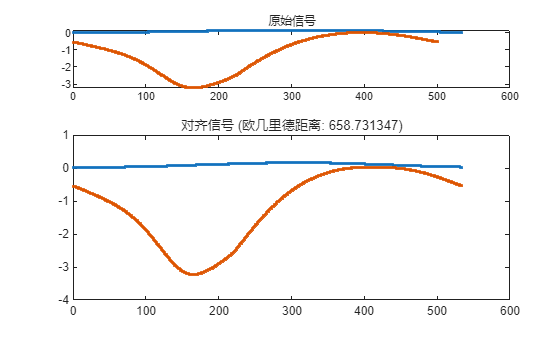

ans = 658.7313

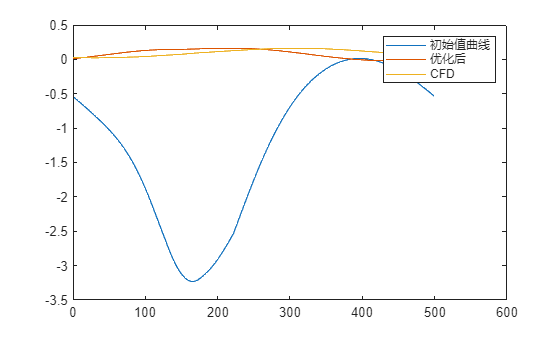

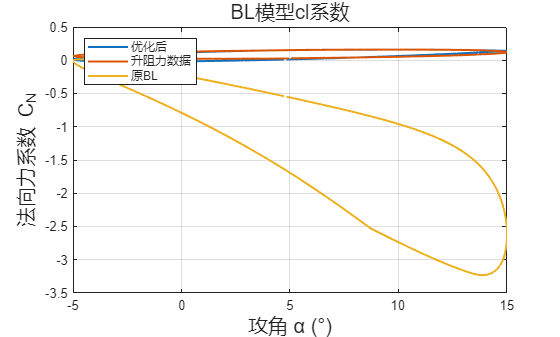

compare_optimal_result_GZ(para_local_GZ,para_init,setcase);